# Third Question

`I used Newton Method as a zero finder to determine the elapsed time required to fall a distance of 1 Km.` 

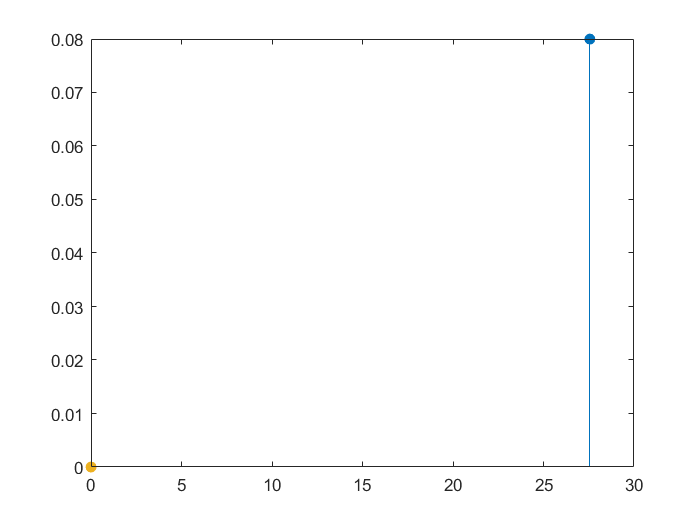

Trail_Members = 'x(1): 22.4379345159150389577 we Have x(1)-x(0) that is:-27.5620654840849610423 && f(x(1)) is 0.0799901364808493220: '

Trail_Members = 'x(2): 22.4364420869294711736 we Have x(2)-x(1) that is:-0.0014924289855671876 && f(x(2)) is 0.0000000119185953853: '

Trail_Members = 'x(3): 22.4364420867070961663 we Have x(3)-x(2) that is:-0.0000000002223731988 && f(x(3)) is 0.0000000000000000000: '

root =     'root finded:22.4364420867070961663 
     Number of goneStages: 3'


g = 9.8065;
k = 0.00341;
x0 = 50; %input('enter the approximate root: ');
syms f(x)
figure();
xlabel("|x(N)-x(N-1)|");
ylabel("f(x(N))");
f(x) = log((cosh(x*sqrt(g*k))))/k - 1000;
df = diff(f,x);
index_N = 1;
while(true)
    x1 = vpa(x0 - (f(x0)/vpa(df(x0))));
    stem(abs(x1-x0),f(x1),'filled')
    hold on
    Trail_Members = sprintf('x(%d): %.19f we Have x(%d)-x(%d) that is:%.19f && f(x(%d)) is %.19f: ',index_N,x1,index_N,index_N-1,x1-x0,index_N,f(x1))
    if(f(x1) == 0 ||  abs(x1-x0)< 10^(-4)) % we use 10^(-4) as the HW says
        root = sprintf('root finded:%0.19f \nNumber of goneStages: %d',x1,index_N)
        break;
    end
 index_N = index_N + 1; 
    x0 = x1;
end

# Forth Question

## `Main solution of the Matrix via Matlab own Functions!`

A = vpa(0);  % in order to make the variables of matrix in vpa mode
B = vpa(0);  % in order to make the variables of matrix in vpa mode
for i=1:5
   for j=1:5
        A(i,j)=vpa(abs((1/3)^(abs(i-j))));
    end
end
for i=1:5
    B(i,1)=vpa((1/7)^i);
end
A % in order to show A

$$A = \left(\begin{array}{ccccc} 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037 & 0.012345679012345679012345679012346\\ 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037\\ 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111\\ 0.037037037037037037037037037037037 & 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333\\ 0.012345679012345679012345679012346 & 0.037037037037037037037037037037037 & 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 \end{array}\right)$$

B % in order to show B

$$B = \left(\begin{array}{c} 0.14285714285714285714285714285714\\ 0.020408163265306122448979591836735\\ 0.0029154518950437317784256559766764\\ 0.00041649312786339025406080799666805\\ 0.000059499018266198607722972570952579 \end{array}\right)$$

% The result
answer = mldivide(A,B)

$$answer = \left(\begin{array}{c} 0.15306122448979591836734693877551\\ -0.029154518950437317784256559766764\\ -0.0041649312786339025406080799666805\\ -0.00059499018266198607722972570952579\\ -0.000089248527399297911584458856428869 \end{array}\right)$$

## `Gauss-Jordan`

AwithB = [A,B]   % in order to use Gauss-Jordan iteration

$$AwithB = \left(\begin{array}{cccccc} 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037 & 0.012345679012345679012345679012346 & 0.14285714285714285714285714285714\\ 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037 & 0.020408163265306122448979591836735\\ 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.0029154518950437317784256559766764\\ 0.037037037037037037037037037037037 & 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.00041649312786339025406080799666805\\ 0.012345679012345679012345679012346 & 0.037037037037037037037037037037037 & 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.000059499018266198607722972570952579 \end{array}\right)$$

GaussAnswer=vpa(0); % matrix of soloution
n=5; % dimension of the A matrix
for i=1:n-1
    for j=i+1:n
        if abs(AwithB(j,i))>abs(AwithB(i,i))
            T=AwithB(j,:);
            AwithB(j,:)=AwithB(i,:);
            AwithB(i,:)=T;
        end
    end
end
disp('After pivoting');

After pivoting


disp(AwithB);

$$\left(\begin{array}{cccccc} 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037 & 0.012345679012345679012345679012346 & 0.14285714285714285714285714285714\\ 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037 & 0.020408163265306122448979591836735\\ 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.0029154518950437317784256559766764\\ 0.037037037037037037037037037037037 & 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.33333333333333333333333333333333 & 0.00041649312786339025406080799666805\\ 0.012345679012345679012345679012346 & 0.037037037037037037037037037037037 & 0.11111111111111111111111111111111 & 0.33333333333333333333333333333333 & 1.0 & 0.000059499018266198607722972570952579 \end{array}\right)$$

for k=1:n-1
    for i=k+1:n
        m=AwithB(i,k)/AwithB(k,k);
        for j=k:n+1
            AwithB(i,j)=AwithB(i,j)-m*AwithB(k,j);
        end
    end
end
disp('Triangularize Form  ');

Triangularize Form  


disp(AwithB);

$$\left(\begin{array}{cccccc} 1.0 & 0.33333333333333333333333333333333 & 0.11111111111111111111111111111111 & 0.037037037037037037037037037037037 & 0.012345679012345679012345679012346 & 0.14285714285714285714285714285714\\ 0 & 0.88888888888888888888888888888889 & 0.2962962962962962962962962962963 & 0.098765432098765432098765432098765 & 0.032921810699588477366255144032922 & -0.027210884353741496598639455782313\\ 0 & 0 & 0.88888888888888888888888888888889 & 0.2962962962962962962962962962963 & 0.098765432098765432098765432098765 & -0.0038872691933916423712342079689018\\ 0 & 0 & 0 & 0.88888888888888888888888888888889 & 0.2962962962962962962962962962963 & -0.00055532417048452033874774399555741\\ 0 & 0 & 0 & 0 & 0.88888888888888888888888888888889 & -0.000079332024354931476963963427936772 \end{array}\right)$$

            
if AwithB(n,n)==0
    disp('No unique solution');
end
    GaussAnswer(n)=AwithB(n,n+1)/AwithB(n,n);
    for j=n-1:-1:1
        sum=0;
        for i=1:n-j
            sum=sum+AwithB(j,n+1-i)*GaussAnswer(n+1-i);
        end
        GaussAnswer(j)=(AwithB(j,n+1)-sum)/AwithB(j,j);
    end 
    GaussAnswer

$$GaussAnswer = \left(\begin{array}{ccccc} 0.15306122448979591836734693877551 & -0.029154518950437317784256559766764 & -0.0041649312786339025406080799666805 & -0.00059499018266198607722972570952579 & -0.000089248527399297911584458856428869 \end{array}\right)$$

   % the error
   for i = 1:5
       sprintf('error of the Gauss jordan(%d element) from the main result of matlab is %.32f:\n and the gauss %d element is: %.32f and the main matlab %d result is %.32f ',i,vpa(abs(answer(i,1)-GaussAnswer(1,i))),i,GaussAnswer(1,i),i,answer(i,1))
   end

ans =     'error of the Gauss jordan(1 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the gauss 1 element is: 0.15306122448979592176598885089334 and the main matlab 1 result is 0.15306122448979592176598885089334 '


ans =     'error of the Gauss jordan(2 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the gauss 2 element is: -0.02915451895043731644907580857762 and the main matlab 2 result is -0.02915451895043731644907580857762 '


ans =     'error of the Gauss jordan(3 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the gauss 3 element is: -0.00416493127863390259768561207920 and the main matlab 3 result is -0.00416493127863390259768561207920 '


ans =     'error of the Gauss jordan(4 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the gauss 4 element is: -0.00059499018266198611636086379661 and the main matlab 4 result is -0.00059499018266198611636086379661 '


ans =     'error of the Gauss jordan(5 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the gauss 5 element is: -0.00008924852739929790932261327585 and the main matlab 5 result is -0.00008924852739929790932261327585 '


## `jacobi`

Ajacobi = vpa(0);  % in order to make the variables of matrix in vpa mode
Bjacobi = vpa(0);  % in order to make the variables of matrix in vpa mode
for i=1:5
   for j=1:5
        Ajacobi(i,j)=vpa(abs((1/3)^(abs(i-j))));
    end
end
for i=1:5
    Bjacobi(i,1)=vpa((1/7)^i);
end
N=100; % 100 iteration
diagonal = diag(diag(Ajacobi)); % strip out the diagonal
diag_deleted = Ajacobi - diagonal; % delete the diagonal	
sol = vpa(0); % initial guess of zero
temp = sol;
    for i = 1:N
    % computing the matrix inverse    
    temp = diagonal \ (Bjacobi - diag_deleted * sol);
    end
sol = temp;
% the error
disp('')
    for i = 1:5
       sprintf('error of the Jacobi(%d element) from the main result of matlab is %.32f:\n and the jacobi %d element is: %.32f and the main matlab %d result is %.32f ',i,vpa(abs(answer(i,1)-sol(i,1))),i,sol(i,1),i,answer(i,1))
    end

ans =     'error of the Jacobi(1 element) from the main result of matlab is 0.01020408163265306041023183780680:
      and the jacobi 1 element is: 0.14285714285714284921269268124888 and the main matlab 1 result is 0.15306122448979592176598885089334 '


ans =     'error of the Jacobi(2 element) from the main result of matlab is 0.04956268221574344073898643614484:
      and the jacobi 2 element is: 0.02040816326530612082046367561361 and the main matlab 2 result is -0.02915451895043731644907580857762 '


ans =     'error of the Jacobi(3 element) from the main result of matlab is 0.00708038317367763389564849774160:
      and the jacobi 3 element is: 0.00291545189504373173164375465660 and the main matlab 3 result is -0.00416493127863390259768561207920 '


ans =     'error of the Jacobi(4 element) from the main result of matlab is 0.00101148331052537633276133810512:
      and the jacobi 4 element is: 0.00041649312786339027061058293278 and the main matlab 4 result is -0.00059499018266198611636086379661 '


ans =     'error of the Jacobi(5 element) from the main result of matlab is 0.00014874754566549652909021594915:
      and the jacobi 5 element is: 0.00005949901826619860621507551723 and the main matlab 5 result is -0.00008924852739929790932261327585 '


`Gauss-Seidel`

ASeidel = vpa(0);  % in order to make the variables of matrix in vpa mode
BSeidel = vpa(0);  % in order to make the variables of matrix in vpa mode
for i=1:5
   for j=1:5
        ASeidel(i,j)=vpa(abs((1/3)^(abs(i-j))));
    end
end
for i=1:5
    BSeidel(i,1)=vpa((1/7)^i);
end
xSeidel=[vpa(0);vpa(0);vpa(0);vpa(0);vpa(0)];
SeidelAnswer=GaussSeidel(ASeidel,bb,xSeidel,100)

Seidel =     0.1429         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292         0

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531         0
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

Seidel =     0.1429    0.1524    0.1530    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531    0.1531
   -0.0272   -0.0290   -0.0291   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292   -0.0292
   -0.0039   -0.0041   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042   -0.0042
   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.00

$$SeidelAnswer = \left(\begin{array}{c} 0.15306122448979591836734693877551\\ -0.029154518950437317784256559766764\\ -0.0041649312786339025406080799666805\\ -0.00059499018266198607722972570952579\\ -0.000089248527399297911584458856428869 \end{array}\right)$$

for i=1:5
   sprintf('error of Gauss-Seidel(%d element) from the main result of matlab is %.32f:\n and the seidel %d element is: %.32f and the main matlab %d result is %.32f',i,vpa(abs(answer(i,1)-SeidelAnswer(i,1))),i,SeidelAnswer(i,1),i,answer(i,1)) 
end

ans =     'error of Gauss-Seidel(1 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the seidel 1 element is: 0.15306122448979592176598885089334 and the main matlab 1 result is 0.15306122448979592176598885089334'


ans =     'error of Gauss-Seidel(2 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the seidel 2 element is: -0.02915451895043731644907580857762 and the main matlab 2 result is -0.02915451895043731644907580857762'


ans =     'error of Gauss-Seidel(3 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the seidel 3 element is: -0.00416493127863390259768561207920 and the main matlab 3 result is -0.00416493127863390259768561207920'


ans =     'error of Gauss-Seidel(4 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the seidel 4 element is: -0.00059499018266198611636086379661 and the main matlab 4 result is -0.00059499018266198611636086379661'


ans =     'error of Gauss-Seidel(5 element) from the main result of matlab is 0.00000000000000000000000000000000:
      and the seidel 5 element is: -0.00008924852739929790932261327585 and the main matlab 5 result is -0.00008924852739929790932261327585'


function y=GaussSeidel(AA,bb,xx,NumIters)
% Runs the Gauss-Seidel method for solving Ax=b, starting with x and
% running a maximum of NumIters iterations.
%
% The matrix A should be diagonally dominant, and in particular,  it should
% not have any diagonal elements that are zero (a division by zero error
% will be produced).
%
% The output y will be the whole sequence of outputs instead of the final
% value (if x is in R^n, then y will be n x NumIters
D=diag(AA);
AA=AA-diag(D);
D=vpa(1./D);  %We need the inverses
n=length(xx);
xx=xx(:); %Make sure x is a column vector
SeidelIter=zeros(n,NumIters);
for j=1:NumIters
for k=1:n
xx(k)=vpa((bb(k)-AA(k,:)*xx)*D(k));
end
SeidelIter(:,j)=xx
end
y=xx;
end

